format short
N = 10;  
p = 0.55;  
q = 0.45;  
a = q/p;  

d_W = zeros(1, N+1);  % Store r_W values for w = 0 to N

for w = 0:N-1
    d_W(w+1) = ((N*(1-a^w))/((p-q)*(1-a^N)))-(w/(p-q));
end

d_W'

ans =          0
   11.0056
   18.1920
   22.2536
   23.7586
   23.1717
   20.8734
   17.1748
   12.3304
    6.5487


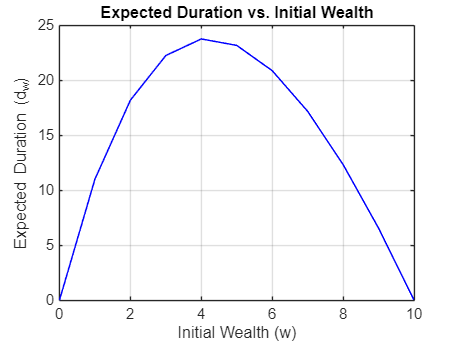

figure;
plot(0:N, d_W, 'b', 'LineWidth', 1);
xlabel('Initial Wealth (w)');
ylabel('Expected Duration (d_w)');
title('Expected Duration vs. Initial Wealth');
grid on;

xlim([0.00 N])